# Preprocesamiento

## Importar

Desde osciloscopio Rigol

%Señales del generador
wave_sqr = readmatrix("data/cuadrada.CSV");
wave_sin = readmatrix("data/senoidal.CSV");
N = length(wave_sin);
fs = 1/2.000E-06 %Hz

fs = 500000


%Señales con ruido
noise_pink_sin = readmatrix("data/sin_pn.CSV");
noise_white_sin = readmatrix("data/sin_wn.CSV");
fs_noise = 1/1.000E-06 %Hz

fs_noise = 1000000

N_noise = length(noise_white_sin);


Desde la grabación de audio

[audio_sqr,fs_audio_sqr] = audioread("data/cuadrado.mp3");
[audio_sin,fs_audio_sin] = audioread("data/sin.mp3");

%recotar a mismo numero de muestras
%Solo un canal
N_audio = min(length(audio_sin),length(audio_sqr));
audio_sqr = audio_sqr(1:N_audio,1);
audio_sin = audio_sin(1:N_audio,1);



Señal del filtro resonante

res_filter = readmatrix("data/scope_csv_27_0.csv");
N_res = length(res_filter);
fs_res = 1/res_filter(1,1);
res_filter = res_filter(:,2);

## Visualizar en tiempo

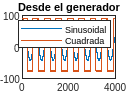

figure
plot(wave_sin)
hold on
plot(wave_sqr)
hold off
legend("Sinusoidal","Cuadrada")
title("Desde el generador")

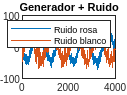


figure
plot(noise_pink_sin)
hold on
plot(noise_white_sin)
hold off
legend("Ruido rosa","Ruido blanco")
title("Generador + Ruido")

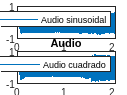


figure
subplot(2,1,1)
plot(audio_sin)
legend("Audio sinusoidal")
subplot(2,1,2)
plot(audio_sqr)
legend("Audio cuadrado")
title("Audio")

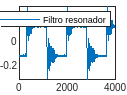


figure
plot(res_filter)
legend("Filtro resonador")

Escuchar 

%sound()

## Espectro

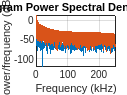

% Periodograma
periodogram([wave_sin wave_sqr],flattopwin(N),N,fs)

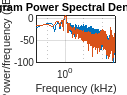


periodogram([noise_white_sin noise_pink_sin],rectwin(N_noise),N_noise*10,fs_noise)
xscale("log")

## Find peaks

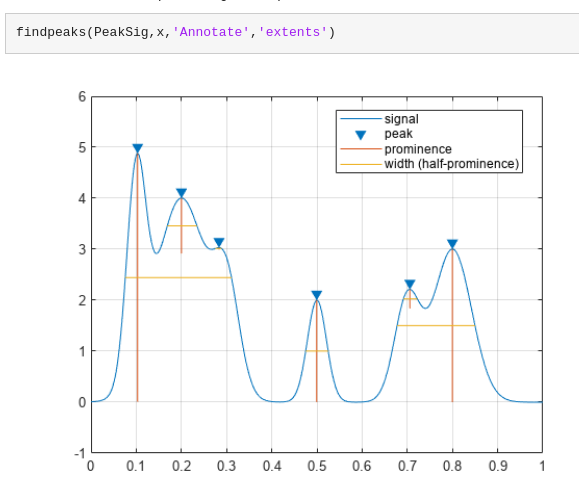

## Step response